# **Progetto regolatore con luogo delle radici**

#### inizializzazione dell'ambiente

clear
close all
clc

#### Definizione della funzione di trasferimento tempo continuo del processo

% parameters
Tau_meca = 0.072;
Tau_sensore = 0.014;
Tau = Tau_sensore + Tau_meca;
T = 0.115;
mu = 1;

% G_ = G not delayed
G_ = tf(mu, [T 1 0]);

% G
G = G_;
G.IODelay = Tau

G =
 
                        1
  exp(-0.086*s) * -------------
                  0.115 s^2 + s
 
Continuous-time transfer function.



**Definizione della funzione di trasferimento tempo discreto del processo**

%discretizzazione di G
Tc = 0.02;
G_d = c2d(G, Tc)

G_d =
 
           0.0008186 z^2 + 0.00224 z + 0.0001339
  z^(-5) * -------------------------------------
                   z^2 - 1.84 z + 0.8404
 
Sample time: 0.02 seconds
Discrete-time transfer function.



G_d = tf([0.0008186 0.00224 0.0001339], [1 -1.84 0.8404 0 0 0 0 0], Tc) %riscritto in forma canonica

G_d =
 
  0.0008186 z^2 + 0.00224 z + 0.0001339
  -------------------------------------
       z^7 - 1.84 z^6 + 0.8404 z^5
 
Sample time: 0.02 seconds
Discrete-time transfer function.



pole(G_d)

ans =          0
         0
         0
         0
         0
    0.9975
    0.8425


**Traccio luogo delle radici di G_d**

% poli e zeri di G_d
[poliG_d, zeriG_d] = pzmap(G_d)

poliG_d =          0
         0
         0
         0
         0
    0.9975
    0.8425


zeriG_d =    -2.6752
   -0.0611


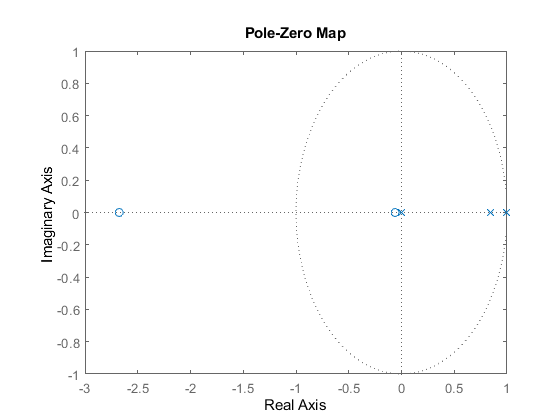

pzmap(G_d)

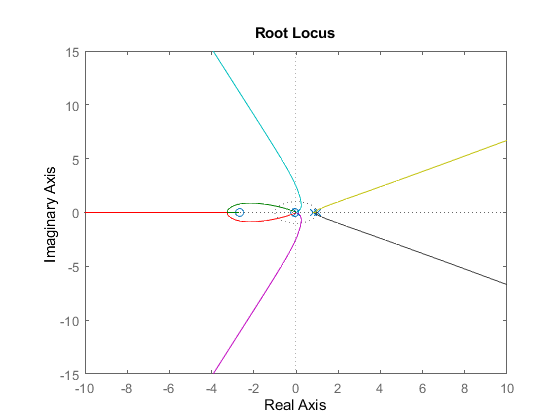


%traccio luogo
rlocus(G_d)

**Opero su luogo delle radici per trovare il regolatore**

% richieste per regolatore:

%  - asintotica stabilità del sistema ad anello chiuso
%  - astatismo a gradino 
%  - tempo assestamento < 1s



%trova il regolatore ed estrai C
%rltool(G_d, Tc)


**Regolatore**

%R trovato = 4.6129z -3.8864
%             --------------
%               z - 0.7


%R = C
R = tf([4.6129 -3.8864], [1 -0.7], Tc)

R =
 
  4.613 z - 3.886
  ---------------
      z - 0.7
 
Sample time: 0.02 seconds
Discrete-time transfer function.



**Funzioni definitive**

L = R * G_d                 %open loop function

L =
 
  0.003776 z^3 + 0.007151 z^2 - 0.008088 z - 0.0005204
  ----------------------------------------------------
        z^8 - 2.54 z^7 + 2.128 z^6 - 0.5883 z^5
 
Sample time: 0.02 seconds
Discrete-time transfer function.



L_close = feedback(L, 1)    %close loop function

L_close =
 
                                                         
     0.003776 z^3 + 0.007151 z^2 - 0.008088 z - 0.0005204
                                                         
  -----------------------------------------------------------
                                                             
  z^8 - 2.54 z^7 + 2.128 z^6 - 0.5883 z^5 + 0.003776 z^3     
                                                             
                      + 0.007151 z^2 - 0.008088 z - 0.0005204
                                                             
 
Sample time: 0.02 seconds
Discrete-time transfer function.



**Qualche test sulla funzione F**

F = L/(1+L)

F =
 
                                                              
   0.003776 z^11 - 0.00244 z^10 - 0.01822 z^9 + 0.03302 z^8   
                                                              
                    - 0.0201 z^7 + 0.00365 z^6 + 0.0003061 z^5
                                                              
  -------------------------------------------------------------
                                                               
  z^16 - 5.08 z^15 + 10.71 z^14 - 11.99 z^13 + 7.519 z^12      
                                                               
          - 2.5 z^11 + 0.3436 z^10 - 0.01822 z^9 + 0.03302 z^8 
                                                               
                   - 0.0201 z^7 + 0.00365 z^6 + 0.0003061 z^5  
                                                               
 
Sample time: 0.02 seconds
Discrete-time transfer function.



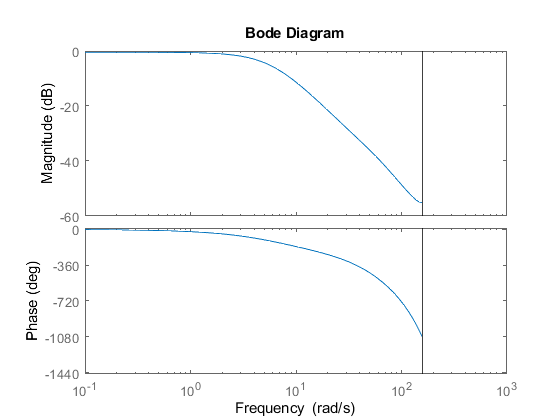


bode(F)

**Qualche test sulla funzione ad anello chiuso**

%TEST

%poles and zeros 
[poli, zeri] = pzmap(L_close)

poli =    0.8959 + 0.0443i
   0.8959 - 0.0443i
   0.8424 + 0.0000i
   0.2005 + 0.3336i
   0.2005 - 0.3336i
  -0.2170 + 0.1895i
  -0.2170 - 0.1895i
  -0.0611 + 0.0000i


zeri =    -2.6752
    0.8425
   -0.0611


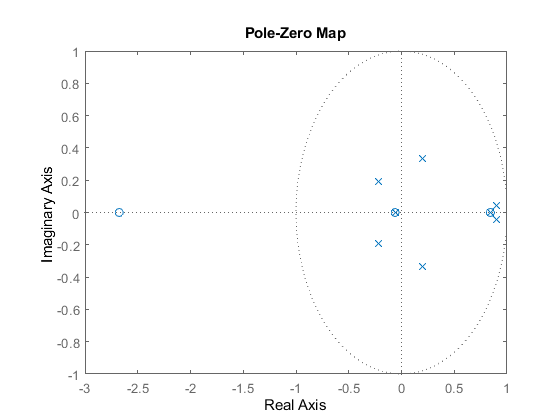

pzmap(L_close)

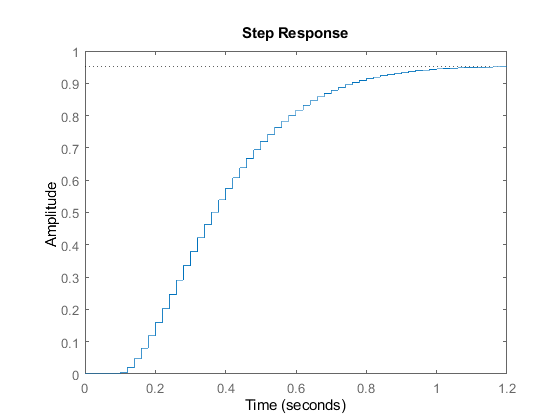



%indicial response
step(L_close)

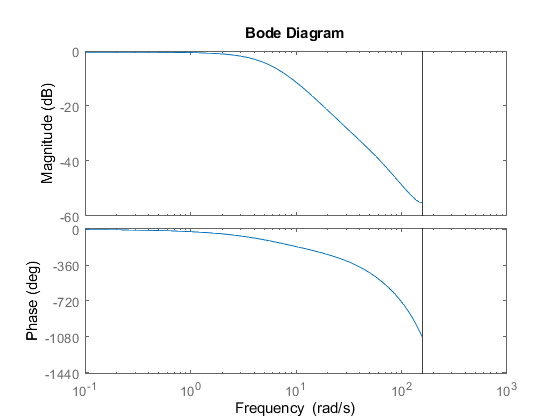



%bode diagram
bode(L_close)